%% EV Battery Range Simulation (Engineering Model)
% This script simulates electric vehicle battery discharge based on speed profile and energy consumption model.


%{
ES115 EV battery range simulation
 Created by Gracy Sylvestre - 02/02/2026
Author: Gracy Sylvestre
Version: 2.0
Date: 2026-04-27


State the problem (Purpose):
 Electric bill costs are compared based on usage values to determine which bill would be most cost effective.

Describe input values (Knowns)and required output (Unknowns) 
    Input: - Linear and Piecewise function
          - usage range
    Output:
        - Graph showcasing expected electricity bill alongside amount of
    electricity used in kWh
       - table of usage values and corresponding bills for both plans
      - intersection point where both bills cost the same
      - plan reccomendations specific to usage value of choice
     
  Engineering Workflow and Algarithems:
   - Piecewise linear modeling
    - Numerical Vectorization 
    - Comparison Logic and Thresholding

MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
    -  if/else/end 
    - plot function
    - table function
    - fprintf
 %}

clear; clc; close all;     % Clear workspace

%user input
batteryE = input("Enter initial battery energy in kWh (e.g., 60): "); % choose starting battery energy
if isempty(batteryE)   %if choice left empty -> default option
    batteryE = 60;
end

mode = input("Enter driving mode (1 = City, 2 = Highway): "); % choose driving style
if isempty(mode)   %if choice left empty -> default option
    mode = 1;
end

duration = input("Enter simulation time in hours (e.g., 2): "); % choose simulation time in total
if isempty(duration) %if choice left empty -> default option
    duration = 2;
end

timestep = 1/60;   % Time step in hours (1 minute resolution)

time = 0:timestep:duration; % vector for time

%parameters 

a = 0.002;   % Aerodynamic coefficient
b = 0.05;    % coefficient for Rolling resistance 
c = 0.5;     % Accessory load (constant power)

% model for speed profile


speed = zeros(size(time)); % generate array for speed

for x = 1:length(time)     %Loop over all time steps
    
    if mode == 1           %if on city driving mode
        
        speed(x) = 15 + 10*sin(0.5*time(x)) + 5*randn; % go at random speed (first stop)
        
        if speed(x) < 0    % negative speed invalid
            speed(x) = 0;
        end
        
    else                   % otherwise (Highway mode)
        
        speed(x) = 30 + 3*sin(0.2*time(x));  % speed stays high with little variation
    end
end

%convert units 
speedms = speed * (1000/3600); %Convert from km/h to m/s

%establish variables

E = zeros(size(time)); % energy of battery over given time
D = zeros(size(time));   %distance traveled energy of battery over given time

E(1) = batteryE;% Initial battery energy

%loop for simulation
for x = 2:length(time)
    
    v = speedms(x); %velocity of current state
    
    % Power consumption model (engineering equation)
    power = a*v^2 + b*v + c;     % Instant power demand (kW approx)
    
    % Update energy (Euler integration)
    E(x) = E(x-1) - power*timestep;
    
    % negative energy invalid (prevention)
    if E(x) < 0
        E(x) = 0;
    end
    
    %Update distance traveled
    D(x) = D(x-1) + v*timestep;
    
    % if battery is empty, simulation comes to a stop
    if E(x) == 0
        E(x:end) = 0;
        D(x:end) = D(x);
        break;
    end
end

%metrics given performance 

TRange = D(find(E>0,1,'last')); %total range

avgSpeed = mean(speed); %average speed of system

energyUsed = batteryE - E(end); %amount of energy used

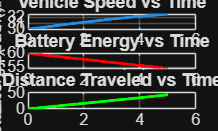

%visuals

figure; %create new figure
subplot(3,1,1); %first subplot
plot(time, speed, 'b', 'LineWidth', 1.5); %plot speed vs time in blue line
title("Vehicle Speed vs Time"); %title the plot created 
xlabel("Time (hr)"); %label horizontal axis
ylabel("Speed (km/h)");% label vertical axis
grid on;

subplot(3,1,2); %second subplot
plot(time, E, 'r', 'LineWidth', 1.5); %plot energy vs time in red line
title("Battery Energy vs Time");%title the plot created
xlabel("Time (hr)"); %label horizontal axis
ylabel("Energy (kWh)"); %label vertical axis
grid on;

subplot(3,1,3); %third subplot
plot(time, D, 'g', 'LineWidth', 1.5); %plot distance vs time in blue line
title("Distance Traveled vs Time");%title the plot created
xlabel("Time (hr)"); %label horizontal axis
ylabel("Distance (m)"); %label vertical axis
grid on;

%results of output
fprintf("\n      EV PERFORMANCE RESULTS      \n");


===== EV PERFORMANCE RESULTS =====



fprintf("Total Distance (Range): %.2f meters\n", max(D)); %display the total distance traveled

Total Distance (Range): 43.59 meters


fprintf("Average Speed: %.2f km/h\n", avgSpeed); %display the average speed of the vehicle

Average Speed: 31.38 km/h


fprintf("Energy Used: %.2f kWh\n", energyUsed); %display the total amount of energy used 

Energy Used: 5.44 kWh


%testing results with sample speeds

fprintf("\n     Testing model sensitivity...      \n");


Testing model sensitivity...



testspeeds = [20 30 40]; % Different constant speeds

for s = testspeeds
    
    testV = s * (1000/3600); % Convert to m/s
    testpower = a*testV^2 + b*testV + c;
    
    fprintf("Speed %.0f km/h → Power Demand %.3f kW\n", s, testpower); %display speed and power demand of test system
end

Speed 20 km/h → Power Demand 0.840 kW
Speed 30 km/h → Power Demand 1.056 kW
Speed 40 km/h → Power Demand 1.302 kW


%final interpretations
fprintf("\nInterpretation:\n");


Interpretation:



if mode == 1
    fprintf("City driving increases energy fluctuations due to stop-and-go motion.\n");
else
    fprintf("Highway driving is more efficient due to steady speed.\n");
end

Highway driving is more efficient due to steady speed.



fprintf("Higher speed increases aerodynamic losses significantly (v^2 term).\n");

Higher speed increases aerodynamic losses significantly (v^2 term).


fprintf("This model shows why EV efficiency drops at high speeds.\n");

This model shows why EV efficiency drops at high speeds.
